**Project 1: Numerical simulation of a model neuron**

Tasks:

1. Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

%Functions_executions(time, timestep,[a,b,c,d,I], type of dunamics)
%regular spiking
[f_RS,dfdt_RS]=Functions_Executions(200,0.01,[0.02,0.2,-65,8,10],1);
%Intrinsically bursting
[f_IB,dfdt_IB]=Functions_Executions(200,0.001,[0.02,0.2,-55,4,10],2);
%chattering
[f_CH,dfdt_CH]=Functions_Executions(200,0.001,[0.02,0.2,-50,2,10],3);
%fast spiking
[f_FS,dfdt_FS]=Functions_Executions(200,0.001,[0.1,0.2,-65,2,10],4);
%Low-threshold spiking
[f_LTS,dfdt_LTS]=Functions_Executions(200,0.001,[0.02,0.25,-65,2,10],5);
%Thalamo-cortical
[f_TC,dfdt_TC]=Functions_Executions(200,0.001,[0.02,0.25,-65,0.05,10],6);
%rezonator
[f_RZ,dfdt_RZ]=Functions_Executions(200,0.001,[0.1,0.26,-65,2,10],7);

2. Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

c=-55;
d=4;
I=10;

k=10;
amax=0.05;
bmax=1;
disp_t=0.005;
[A,B,out] = Regimemap(c,d,I,k,disp_t,amax,bmax);

3. Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

[f_RS,dfdt_RS]=Functions_Executions(1000,0.01,[0.02,0.2,-65,8,10,1],1);

4. Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

t=100;
dt=0.01;

a=0.03;
b=0.2;
c=-55;
d=2;
I=10;
D=0;
w=-0.05;

v0=c;
u0=b*v0;
f0=[v0,u0,v0/2,u0/2];
const=[a,b,c,d,I,D,w];

fun=@Izhikevich_Neuron_model_with_coupling;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);

[f_c,dfdt_c]=RungeKutta(t,dt,[v0,u0],const,@Izhikevich_Neuron_model,add_func);
Visualization(f(:,1),[f(:,2),f(:,4),f_c(:,2)],"t, ms","v(t)","Two coupling neurons",[],[],["first neuron", "second neuron", "without coupling"])

5. Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.

t=250;
dt=0.01;

a=0.02;
b=0.2;
c=-65;
d=8;
I=10;
D=1;
w=0.001;
const=[a,b,c,d,I,D,w];

v0=c;
u0=b*v0;
n=25;
f0=[];
f0i=[v0,u0];
for i=1:n
    f0=[f0,f0i];
    f0i=[v0,u0].*(1-0.1*rand(1,2));
end

fun=@Izhikevich_Neuron_model_with_coupling;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);

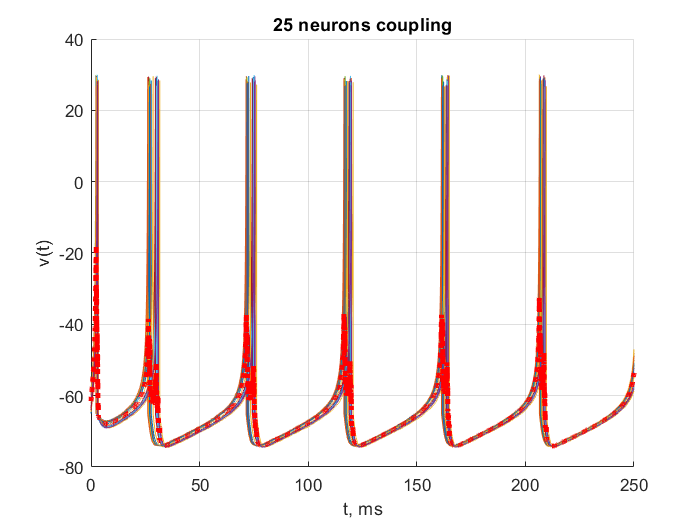

time=f(:,1);
y=mean(f(:,2:2:2*n)')';
max_tau=100;
steps_tau=100;

Visualization(f(:,1),f(:,2:2:2*n),"t, ms","v(t)","Coupling 25 neurons",[],[],[]);
plot(f(:,1),y,":r","LineWidth",3)

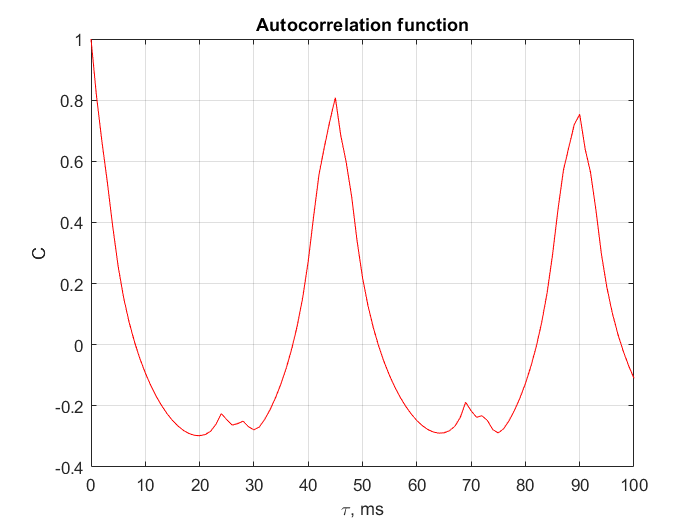

[C,tau,tau_c]=Autocorrelation_function(y,dt,t,max_tau,steps_tau);
Visualization(tau,C,"\tau, ms","C","Autocorrelation function",[],[],[]);

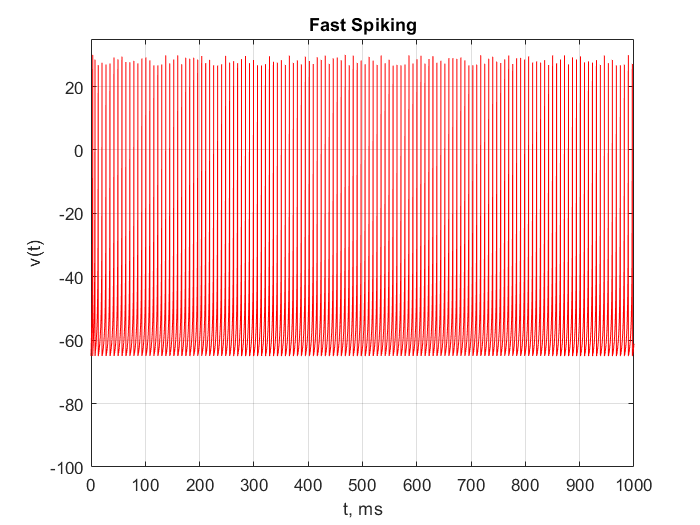

t=1000;
dt=0.01;

param=[[0.02,0.2,-65,8,10];
       [0.02,0.2,-55,4,10];
       [0.02,0.2,-50,2,10];
       [0.1,0.2,-65,2,10];
       [0.02,0.25,-65,2,10];
       [0.02,0.25,-65,0.05,10];
       [0.1,0.26,-65,2,10]];
i=4;
[f,dfdt]=Functions_Executions(t,dt,param(i,:),i);

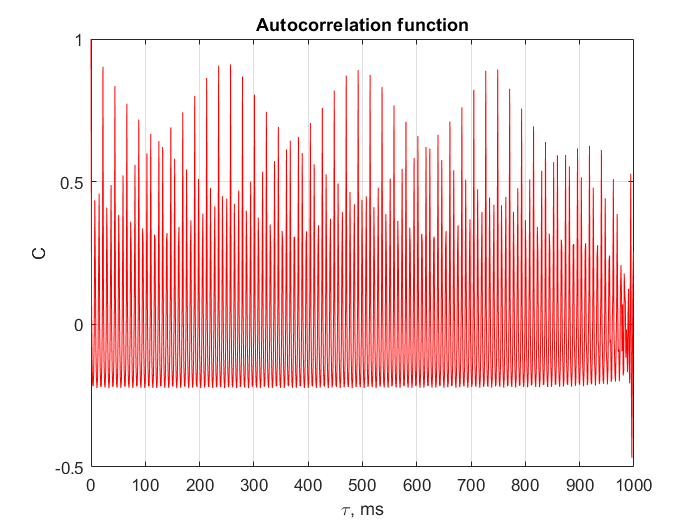

max_tau=1000;
steps_tau=1000;
% v=f(:,2:2:2*n);
% v=mean(v')';
[C,tau,tau_c]=Autocorrelation_function(f(:,2),dt,t,max_tau,steps_tau);
Visualization(tau,C,"\tau, ms","C","Autocorrelation function",[],[],[]);